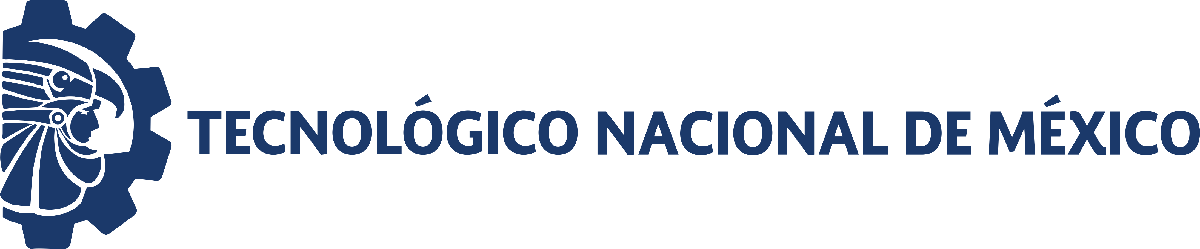                                 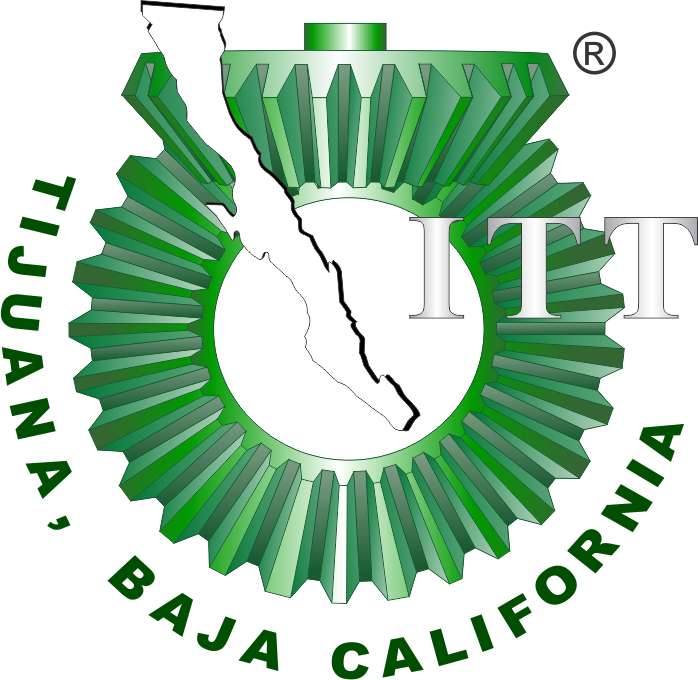

# Práctica tres: Sistema cardiovascular

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

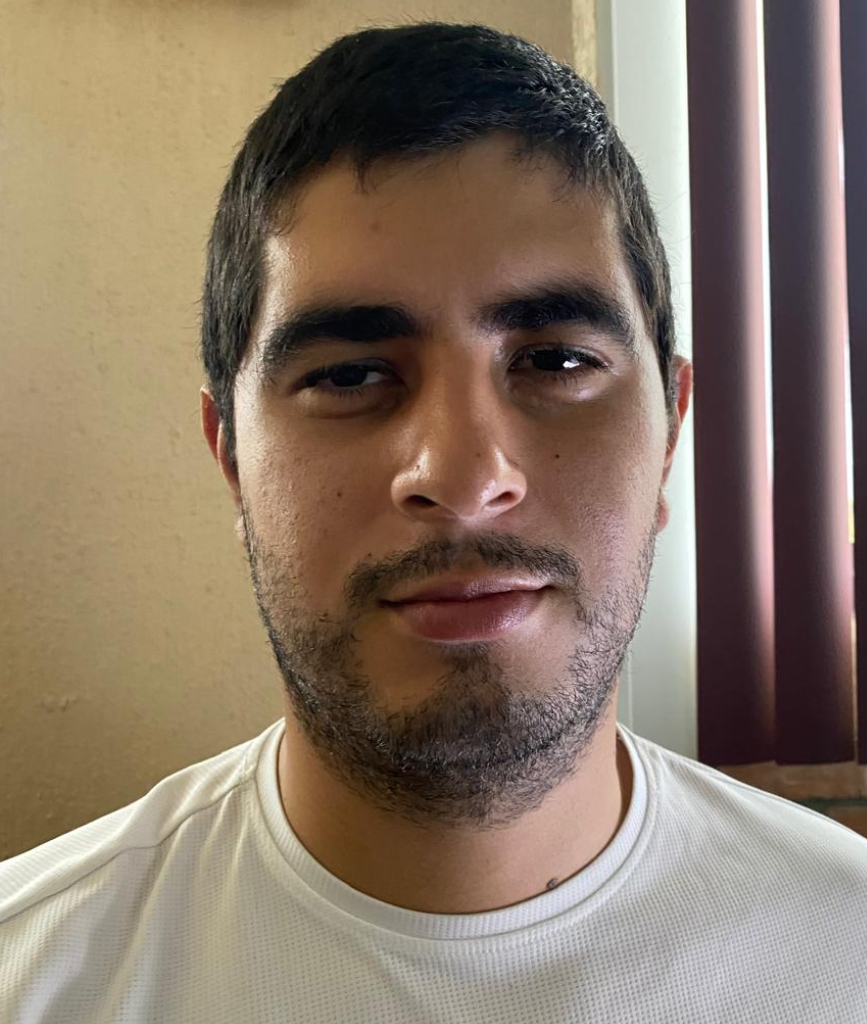

Nombre del alumno: **Edgar Iván Rivas Rosas**

Número de control: **21212748**

Correo institucional:** l21212748@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
tend = "10";
parameters.StopTime = tend;
parameters.Solver = "ode15s";
parameters.MaxStep = "1E-3";
Controlador = "PID";

## Lazo Abierto

file = "sys4_LA";
Signal = 'Lazo abierto'

Signal = 'Lazo abierto'

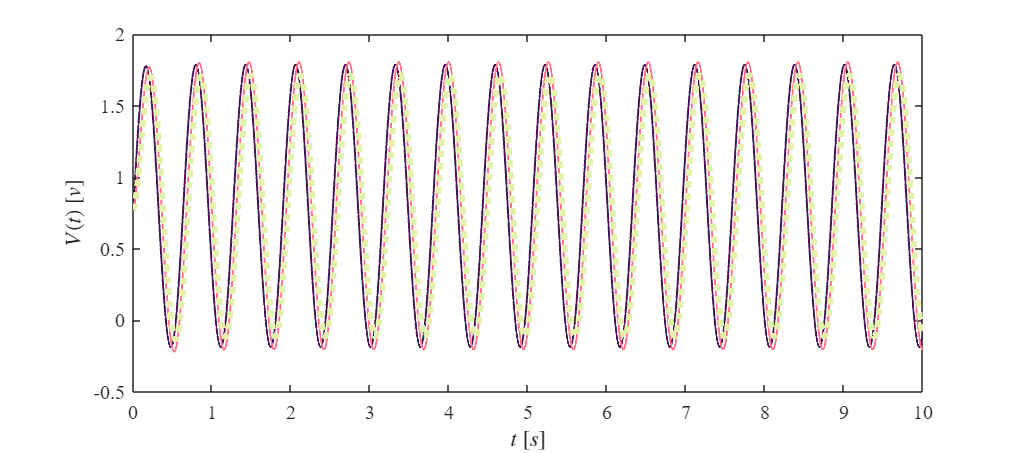

open_system(file);
x = sim(file,parameters);
plotsignals(x.t,x.Hipo,x.Normo,x.Hiper,Signal)

## Rendimiento del controlador hipotenso

kI = 103.32809

Settling time = 0.0386

Overshoot = 0.0384%

Peak = 1

## Hipotenso

file = "sys4_LC_Hipo";
Signal = 'Controlador hipotenso'

Signal = 'Controlador hipotenso'

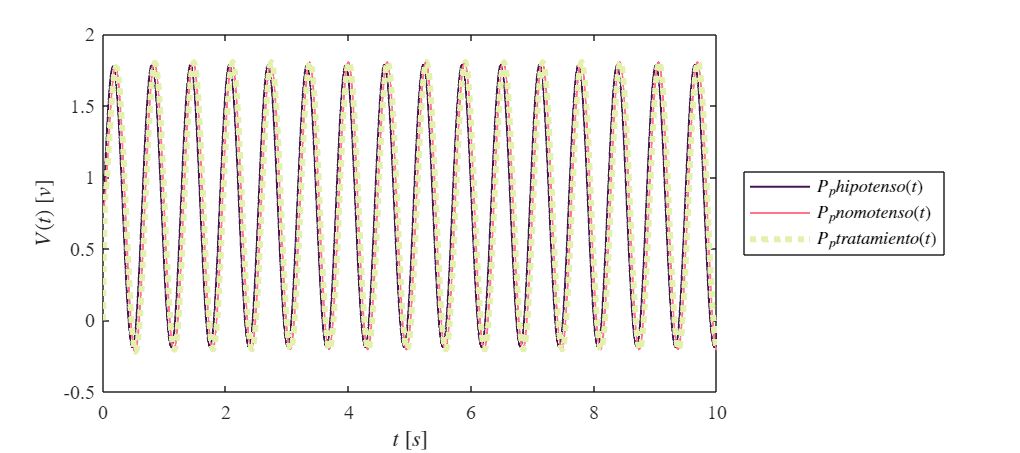

open_system(file);
x1 = sim(file,parameters);
plotsignals(x1.t,x1.Ppx,x1.Ppy,x1.Ppz,Signal)

## Rendimiento del controlador hipertenso

kI = 495.72

Settling time = 0.00816

Overshoot = 0%

Peak = 1

## Hipertenso

file = "sys4_LC_Hiper";
Signal = 'Controlador hipertenso'

Signal = 'Controlador hipertenso'

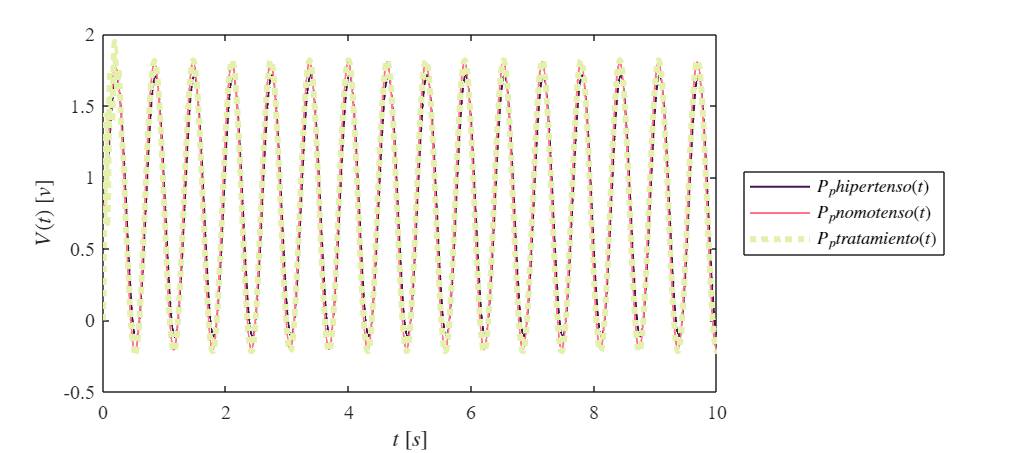

open_system(file);
x2 = sim(file,parameters);
plotsignals(x2.t,x2.Ppx,x2.Ppy,x2.Ppz,Signal)

## Función: Respuesta a las señales

function plotsignals(t, Ppx, Ppy, Ppz, Signal)
    set(figure(), 'Color', 'w')
    set(gcf, 'units', 'Centimeters', 'Position', [1,1,18,8])
    set(gca, 'FontName', 'Times New Roman')
    fontsize(10,'points')
    
    morado = [68/255, 23/255, 82/255];
    rosa =[255/255, 116/255, 139/255];
    %naranja =[255/255, 101/255, 0/255];
    verde =[228/255, 241/255, 172/255];

    hold on; grid off, box on;

    plot (t, Ppx, 'LineWidth', 1, 'Color', morado)
    plot (t, Ppy, 'LineWidth', 1, 'Color', rosa)
    plot (t, Ppz, ':', 'LineWidth', 3, 'Color', verde)

    xlabel('$t$ $[s]$', 'Interpreter', 'Latex')
    ylabel('$V(t)$ $[v]$', 'Interpreter', 'Latex')


   
    if Signal == "Lazo Abierto"
         L = legend('$P_{p}{hipotenso}(t)$',  '$P_{p}{nomotenso}(t)$', '$P_{p}{hipertenso}(t)$');
         set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")

    elseif Signal == "Controlador hipotenso"
        L = legend('$P_{p}{hipotenso}(t)$',  '$P_{p}{nomotenso}(t)$', '$P_{p}{tratamiento}(t)$');
        set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")

    elseif Signal == "Controlador hipertenso"
        L = legend('$P_{p}{hipertenso}(t)$',  '$P_{p}{nomotenso}(t)$', '$P_{p}{tratamiento}(t)$');
        set(L,"Interpreter","Latex","Location",'eastoutside',"Box","On")
        
    end
    %exportgraphics (gcf, [Signal,'.pdf'], 'ContentType', 'Vector')
end